**Import Data**

tic
warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames');
% read data from excel S&P500.csv
StockData = readtable('S&P500.csv','ReadVariableNames',true);

**Pre-Proccessing**

%Ensures the data is the correct data type
if isnumeric(StockData.Open) == false
    Open =cellfun(@str2double,StockData.Open);
    High = cellfun(@str2double,StockData.High);
    Low = cellfun(@str2double,StockData.Low);
    Close = cellfun(@str2double,StockData.Close);
    AdjustedClose = cellfun(@str2double,StockData.AdjClose);
    Volume = cellfun(@str2double,StockData.Volume);
else
    Open = StockData.Open;
    High = StockData.High;
    Low = StockData.Low;
    Close = StockData.Close;
    AdjustedClose = StockData.AdjClose;
    Volume =  StockData.Volume;
end
Date = StockData.Date;

%Changes the data from table to timetable
StockData_TimeTable = timetable(Date,Open,High,Low,Close,Volume);

%Checks for missing Data
%Fills the missing data with previous value
if any(any(ismissing(StockData_TimeTable)))==true
    StockData_TimeTable = fillmissing(StockData_TimeTable,'previous');
end


Normallizes the data. 

StockData_TimeTable = normalize(StockData_TimeTable,"zscore");

Data splitting

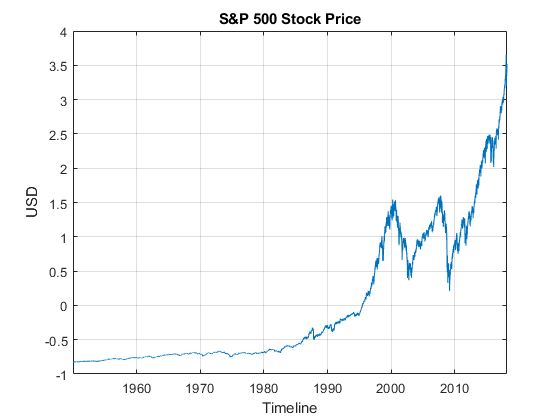

plot(StockData_TimeTable.Date,StockData_TimeTable.Close);
title('S&P 500 Stock Price');
ylabel('USD');
xlabel('Timeline');
grid on

% get Year data out
trainingStart_date = '2010-01-01';
trainingEnd_date = '2010-12-31';
tr = timerange(trainingStart_date, trainingEnd_date);
StockData_TimeTable_2016 = StockData_TimeTable(StockData_TimeTable.Date(tr),:);
% clear unwanted variables
clear ('Open','Close','Date','AdjustedClose','High','Low','Volume','tr','StockData');

## Exploratory Data Analysis

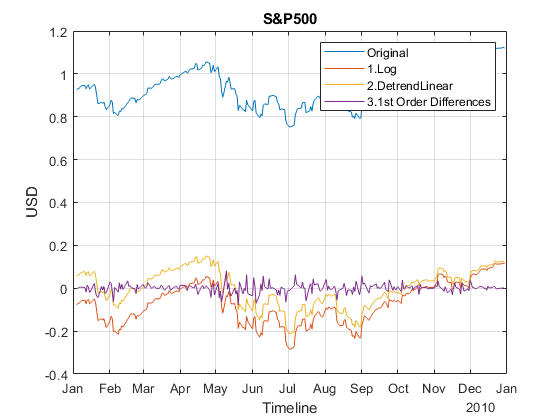

% Transform Data into Stationary Data

% Log
StockData_TimeTable_2016.CloseLog = log(StockData_TimeTable_2016.Close);

% Remove Linear trend
StockData_TimeTable_2016.CloseLogLinear = detrend(StockData_TimeTable_2016.CloseLog);

%Perform Differences
CloseLogLinearDifferences = diff(StockData_TimeTable_2016.CloseLogLinear);

%View the data
figure
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.Close);
hold on
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.CloseLog);
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.CloseLogLinear);
plot(StockData_TimeTable_2016.Date(2:end),CloseLogLinearDifferences);
title('S&P500');
ylabel('USD');
xlabel('Timeline');
legend('Original','1.Log','2.DetrendLinear','3.1st Order Differences')
grid on
hold off

% Test Stationary
% Hypothesis test : Augmented Dickey-filer, KPSS, Leybourne-McCabe, Philip-Peron, Variance Ratio
% Hypothesis test : Egale's ARCH, Ljung-Box Q-test
[h,~] = adftest(CloseLogLinearDifferences);
% if test is valid, it will return 1 or else 0
% P-Value will also verify the stationarity of data, It may get extremely low if your data is not valid.
display(h)

h = logical
   1


## **Find the best fit model of ARIMA**

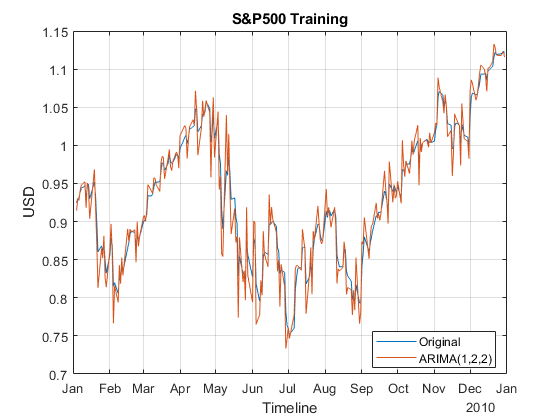

ARIMA_CloseFinal = arima(8,2,8);
[ARIMA_CloseFinal,~,~] = estimate(ARIMA_CloseFinal,StockData_TimeTable_2016.Close,'display','off');

residual = infer(ARIMA_CloseFinal,StockData_TimeTable_2016.Close);
prediction = StockData_TimeTable_2016.Close + residual;

figure
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.Close);
hold on
plot(StockData_TimeTable_2016.Date,prediction);
title('S&P500 Training');
ylabel('USD');
xlabel('Timeline');
legend('Original','ARIMA(1,2,2)','Location','best');
grid on
hold off

## FORECASTING THE DATA

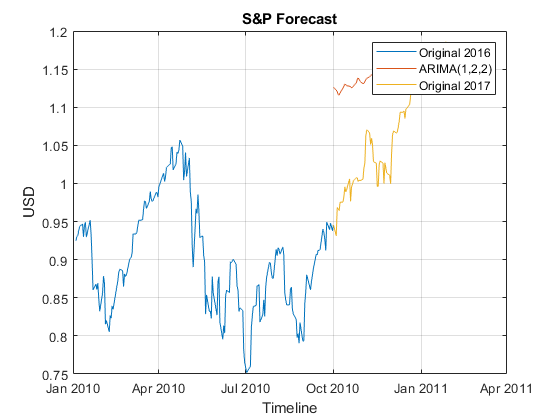

% sets the time range for the predication
tr = timerange('2010-10-01','2011-01-30');
StockData_TimeTable_2017=StockData_TimeTable(StockData_TimeTable.Date(tr),:);
len=length(StockData_TimeTable_2017.Close);
ARIMA_CloseFinalForecast2 = forecast(ARIMA_CloseFinal,len,'Y0',StockData_TimeTable_2016.Close);
%plots the forecast
figure
plot(StockData_TimeTable_2016.Date,StockData_TimeTable_2016.Close);
hold on
% forecast
plot(StockData_TimeTable_2017.Date,ARIMA_CloseFinalForecast2);
plot(StockData_TimeTable_2017.Date,StockData_TimeTable_2017.Close);
title('S&P Forecast');
ylabel('USD');
xlabel('Timeline');
legend('Original 2016','ARIMA(1,2,2)','Original 2017');
grid on
hold off

observed = StockData_TimeTable_2017.Close;
prediction = ARIMA_CloseFinalForecast2;
mape = mean(abs((observed - prediction)./observed))*100

mape = 8.0691

toc

Elapsed time is 57.588810 seconds.
